## CLEAR

clc, clear all, close all
% full parallelepiped for TUG and LLM
% height = 13.18 m
% width = 13.18 m
% length = 13.4 m

## Launch-Landing Module & Space Tug

% LLM Parameters
LLM.name = "Launch-Landing Module";
LLM.color = [0.8 0.2 0.2];

LLM.propellant.mass = 7131;
LLM.propellant.isp = 460;

LLM.mass.dry = 5000;
LLM.mass.wet_descent = LLM.mass.dry + LLM.propellant.mass;

% LLM.size.height = 7;
% LLM.cog = [0 0 LLM.size.height/2];
% if LLM.type == "cylinder"
%     LLM.size.radius = 4;
%     LLM.area_inertia = inertia_cylinder(LLM.size.radius, LLM.size.height);
% elseif LLM.type == "hollow_cylinder"
%     LLM.size.radius_out = 3.8;
%     LLM.size.radius_in = 1.8;
%     LLM.area_inertia = inertia_hollow_cylinder(LLM.size.radius_in,LLM.size.radius_out,LLM.height);
% end

% Thruster Main Engine
LLM.main_engine.Fmax = 240000;
LLM.main_engine.tau = 1.2;
LLM.main_engine.u_min = 0.1; % Minimum percentage for throttability
LLM.main_engine.gimbal_deg = 10; % max angle of gimbal
LLM.main_engine.gimbal_rad = pi/180*10;
LLM.main_engine.misallignment_alpha = 0.05; % deg
LLM.main_engine.misallignment_beta = 180; % deg
LLM.main_engine.misallignment_offset = 0.2; % deg

% Reaction Control System
LLM.rcs.Fmax = 300;
LLM.rcs.tau = 0.8;
LLM.rcs.num_thruster_per_axis = 2; % number of thrusters for each axis in one versus
LLM.rcs.isp = 420;
LLM.rcs.misallignment_alpha = 0.3; % deg
LLM.rcs.misallignment_beta = 180; % deg
LLM.rcs.misallignment_offset = 2; % deg

% ST Parameters
ST.name = "Space Tug";
ST.color = [0.8 0.2 0.2];

ST.propellant.mass = 7212;
ST.propellant.isp = LLM.propellant.isp;

ST.mass.dry = 3000;
ST.mass.wet = ST.mass.dry + ST.propellant.mass;

% ST.size.radius = 2; 
% ST.size.height = 8;
% ST.size.offset = 4.5; % if 0, ST attach on the upper lander surface; if > 0, it will be shifted down, in the lander hole

ST.color = [1 0.5 0.2]; % RGB

% ST.area_inertia = inertia_cylinder(ST.size.radius, ST.size.height);
% ST.cog = [0 0 ST.size.height/2 + LLM.size.height-ST.size.offset];

llm_st_width = 13.18;
llm_st_length = 13.18;
llm_st_height = 13.4;

llm_st_inertia_box = inertia_box(llm_st_width,llm_st_length,llm_st_height);
llm_st_cog = [0 0 llm_st_height/2];

## GEO Target

% GEO Sat Parameters
GEOSAT.name = "GEO Satellite";
GEOSAT.type = "box";

GEOSAT.propellant.mass = 0;

GEOSAT.mass.dry = 3000;
GEOSAT.mass.wet = GEOSAT.mass.dry + GEOSAT.propellant.mass;

GEOSAT.size.length = 4;
GEOSAT.size.width = 4;
GEOSAT.size.height = 5 ;
GEOSAT.color = [0.8 0.2 0.2];

% GEO Sat Inertia Matrix
GEOSAT.area_inertia = inertia_box(GEOSAT.size.height, GEOSAT.size.width, GEOSAT.size.length);

GEOSAT.cog = [0 0 GEOSAT.size.height/2+llm_st_height/2];

## Multi-Body System in Landing Phase

%%% Multi-Body Center of Mass

Mi = LLM.mass.wet_descent + ST.mass.dry + GEOSAT.mass.dry; % Initial mass at Landing
Mf = LLM.mass.dry + ST.mass.dry + GEOSAT.mass.dry; % Final mass after touchdown
% 
% N = 1000; % Number of points in in the plot
% LLM_mass_landing = linspace(Mf,Mi,N);
% COM_values = [];
% 
% for i = LLM_mass_landing
%     r_com = (i*LLM.cog + ...
%              ST.mass.dry*ST.cog + ...
%              GEOSAT.mass.dry*GEOSAT.cog)/i;
%     COM_values = [COM_values, r_com'];
% end
% 
% figure
% plot(LLM_mass_landing, COM_values(3,:), '-')
% xlabel('Multi-Body Mass [kg]')
% ylabel('Z COM [m]')
% grid on
% title('Z-CoM Variation')
% %%% Multi-Body Total Inertia during Descent Phase
% 
% % CoM di ciascun corpo come COLONNE 3xN
% centers_of_mass = [LLM.cog.' , ST.cog.' , GEOSAT.cog.'];  % 3x3, colonne = corpi
% 
% ST.mass_inertia    = ST.mass.dry    * ST.area_inertia;     % 3x3
% GEOSAT.mass_inertia = GEOSAT.mass.dry * GEOSAT.area_inertia; % 3x3
% 
% Inertia_MB = zeros(3,3,numel(LLM_mass_landing));  % array 3x3xN per salvare tutte le matrici
% k = 1;
% for mLLM = LLM_mass_landing
%     masses   = [mLLM, ST.mass.dry, GEOSAT.mass.dry];       % 1x3
%     inertias = { mLLM*LLM.area_inertia , ST.mass_inertia , GEOSAT.mass_inertia }; % 1x3 cell di 3x3
%     I_total  = total_inertia(masses, centers_of_mass, inertias);
%     Inertia_MB(:,:,k) = I_total;
%     k = k + 1;
% end
% 
% % (facoltativo) verifica i fuori-diagonale nell’ultima istanza
% It = Inertia_MB(:,:,end);
% It = 0.5*(It+It.');  % simmetrizza
% off = norm([It(1,2) It(1,3) It(2,3)]);
% fprintf('||offdiag|| = %.3e\n', off);

## Plots

% % 3D models
% plot_stack(LLM.size.radius, LLM.size.height, ...
%            ST.size.radius, ST.size.height, ...
%            GEOSAT.size.height,GEOSAT.size.width,GEOSAT.size.length, ...
%            LLM.cog,ST.cog,GEOSAT.cog, COM_values(:,1000), ST.size.offset,'Multi-Body INITIAL Mass for Landing Phase')
% plot_stack(LLM.size.radius, LLM.size.height, ...
%            ST.size.radius, ST.size.height, ...
%            GEOSAT.size.height,GEOSAT.size.width,GEOSAT.size.length, ...
%            LLM.cog,ST.cog,GEOSAT.cog, COM_values(:,1), ST.size.offset,'Multi-Body FINAL Mass for Landing Phase')

## RCS Torque/Force Limit due to GEO target's CoM misalignment

% Since ee are going to design the launch-landing module and the space tug,
% let's assume that their center of masses are going to be aligned.
% Evaluate torque to be applied by RCS in case the CoM of the GEO target
% has the CoM not aligned. Suppose it's shifted along X-axis

% r = LLM.size.radius;
% GEO_com = linspace(0,1.5,1000);
% 
% Torque_misallignment = GEOSAT.mass.dry * 1.622 * GEO_com;
% F_rcs = Torque_misallignment / r;
% 
% % Max Torque and Force. TO BE UPDATED based on real RCS
% limit_torque = 300;
% limit_force = limit_torque / r;
% 
% limit_force = 300; % assuming 2 RCS activated in both directions, 500 N (more or less the force of the RCS thrusters of Altair Lander)
% limit_torque = limit_force * r;
% 
% figure
% 
% % ---- Subplot 1: Torque ----
% subplot(2,1,1)
% plot(GEO_com, Torque_misallignment, 'k-', 'LineWidth', 1.5); hold on; grid on
% yline( limit_torque, 'r--', 'Torque limit', 'LabelHorizontalAlignment','center');
% title('Torque due to GEO target CoM misalignment')
% xlabel('GEO target X-CoM [m]')
% ylabel('Torque [Nm]')
% legend('Torque demand','Location','best'); hold off
% 
% % ---- Subplot 2: Force ----
% subplot(2,1,2)
% plot(GEO_com, F_rcs, 'b-', 'LineWidth', 1.5); hold on; grid on
% yline( limit_force, 'r--', 'Force limit', 'LabelHorizontalAlignment','center');
% title('RCS force to counteract GEO target CoM misalignment')
% xlabel('GEO target X-CoM [m]')
% ylabel('Force [N]')
% legend('Force demand','Location','best'); hold off

## Gimbal

% % Parameters
% gimbal_angle = 7; % [deg]
% Fmax = LLM.main_engine.Fmax; % Engine maximum thrust [N]
% 
% % Extract minimum and maximum values of the COM-force distance
% d_F_com_min = COM_values(3,1000); 
% d_F_com_max = COM_values(3,1);
% 
% % Create a range of values between min and max
% d_F_com = linspace(d_F_com_min, d_F_com_max, 200);
% 
% % Compute lever arm and torque
% lever = d_F_com .* sind(gimbal_angle);
% T = Fmax .* lever;
% 
% % Plot
% figure;
% plot(d_F_com, T, 'b-', 'LineWidth', 2);
% grid on;
% xlabel('Distance COM - Force [m]');
% ylabel('Torque [Nm]');
% title('Torque generated by gimbaled engine');

% % Offset laterale del CoM
% xc = 0.0;   % [m]
% 
% % Valori di quota del CoM da testare
% zc_values = 6:0.5:9;   % [m]
% 
% % Range di angoli
% alpha_deg = linspace(0,60,200);
% alpha_rad = deg2rad(alpha_deg);
% 
% % Plot
% figure; hold on; grid on; box on;
% 
% for i = 1:length(zc_values)
%     zc = zc_values(i);
%     D = 2*(abs(xc) + zc*tan(alpha_rad));
%     plot(alpha_deg, D, 'LineWidth', 2, ...
%         'DisplayName', sprintf('z_c = %.2f m', zc));
% end
% ylim([13 18]);
% xlabel('\alpha [deg]');
% ylabel('D min [m]');
% title('Minimum Base Area Width vs Inclination \alpha varying Zcom');
% legend show;

## Simulation

% Parameters
g_moon = 1.62;  % m/s^2
g0 = 9.81;      % m/s^2

f_plant = 100;
f_controller = 50;
f_guidance = 1;

sigma_pos = 1;
sigma_vel = 0.015;

% Navigation
% Attitude Sensor Suite
sig_st = 3e-4;      % [rad] Star Tracker
sig_cam = 0.017;    % [rad] Camera with markers
sig_g = 5e-5;       % [rad/s/Hz] IMU
sig_bg = 1e-5;      % [rad/s/sqrt(s)] IMU
f_IMU = 100;        % [Hz] IMU frequency
Ts = 0.01;
Q = 7;
R = 0.05;

mass_err_perc = 10;

%% RCS Model
km = 4.25;
tau = 0.8;
Uon = 0.3;
Uoff = 0.1;
min_on = 0.05;
min_off = 0.1;
dwell_param = [Uon; Uoff; min_on; min_off];
db = 0*[-100 100];
db_omega = 0.05*pi/180;

% Initial state
% initial position and velocity
% x0  = 273370.184839349;        % initial downrange to target (m)
% z0  = 19705.3448611866;
% y0  = -4772.24476929666; 
% vx0 = -1754.69151012538;                    % horizontal speed toward target (m/s) (negative if x decreases)
% vz0 = 0;  
% vy0 = -6.06285837137347;                       % vertical descending speed (m/s, negative downward)
% r0 = [x0; y0; z0];
% v0 = [vx0; vy0; vz0];

x0  = 289448.1899567346;        % initial downrange to target (m)
z0  = 15e3;
y0  = 0e3; 
vx0 = -1695;                    % horizontal speed toward target (m/s) (negative if x decreases)
vz0 = 0;  
vy0 = 0 ;                       % vertical descending speed (m/s, negative downward)
r0 = [x0; y0; z0];
v0 = [vx0; vy0; vz0];

% GUIDANCE LAW
% Breaking phase
    x1_t  = 25000;    y1_t = 0;    z1_t  = 7936.75104830166;  % position targets at end of phase 1
    vx1_t = -202;     vy1_t = 0;   vz1_t = -49.09;            % velocity targets at end of phase 1
    Tgo1  = max(10, (x1_t - x0) / (0.5*(vx0 + vx1_t)));
    tgo_breaking  = Tgo1 + 5;   % add a few seconds buffer to ease transitions (if needed)
    rt_breaking = [x1_t; y1_t; z1_t];
    vt_breaking = [vx1_t; vy1_t; vz1_t];
    target_breaking = [rt_breaking vt_breaking];
% Approach phase
    x2_t   = 0;      y2_t = 0;     z2_t   = 100;              % position targets at end of phase 2
    vx2_t  = 0;      vy2_t = 0;    vz2_t  = -8;               % velocity targets entering vertical phase
    ax2_t  = 0;      ay2_t = 0;    az2_t  = 1.2*g_moon;       % target acceleration at end of phase 2 (hover ~1.2 g)
    Tgo2  = max(10, (x2_t - x1_t) / (0.5*(vx1_t + vx2_t)));
    tgo_approach  = Tgo2 + 5;   % add a few seconds buffer to smooth approach phase
    rt_approach = [x2_t; y2_t; z2_t];
    vt_approach = [vx2_t; vy2_t; vz2_t];
    at_approach = [ax2_t; ay2_t; az2_t];
    target_approach = [rt_approach vt_approach at_approach];
% Vertical descent
    az3_t = 1.2*g_moon;     % target vertical thrust accel in final phase (~1.2 g_moon)
    vx_tol_touch = 0.5;     % horizontal velocity tolerance at touchdown (m/s)
    vy_tol_touch = 0.5;     % horizontal velocity tolerance at touchdown (m/s)
    vz3_t = -1.0;           % target touchdown vertical speed (m/s ~ -1)
    target_vdesc = [vx_tol_touch; vy_tol_touch; vz3_t; az3_t];
    f_cut = 0.5;

% CONTROL LAW
% Control Parameters
kr = 8*[0.5 0.5 0.8]';
ka = 0.2*kr;

% Initial attitude
c0 = (-2*(vt_breaking+2*v0))/tgo_breaking + 6*(rt_breaking - r0)/(tgo_breaking^2);
eul0 = force2eul(c0);
q0 = eul2quat(eul0);

%% ====== Funzioni di supporto (nello stesso file va benissimo) ======
function draw_axis(o, dir, L, c, labeltxt)
    dir = dir / norm(dir);
    v = dir * L;
    quiver3(o(1), o(2), o(3), v(1), v(2), v(3), 0, ...
        'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', c);
    text(o(1)+1.05*v(1), o(2)+1.05*v(2), o(3)+1.05*v(3), ['  ' labeltxt], ...
        'FontWeight','bold', 'Color', c);
end

function R = dcm_from_quat(q) % q = [w x y z]
    q = q(:).'/norm(q);
    w=q(1); x=q(2); y=q(3); z=q(4);
    R = [1-2*(y^2+z^2),   2*(x*y - z*w), 2*(x*z + y*w);
         2*(x*y + z*w), 1-2*(x^2+z^2),   2*(y*z - x*w);
         2*(x*z - y*w),   2*(y*z + x*w), 1-2*(x^2+y^2)];
end

function R = dcm_from_euler321(yaw, pitch, roll) % Z-Y-X
    cy=cos(yaw);  sy=sin(yaw);
    cp=cos(pitch);sp=sin(pitch);
    cr=cos(roll); sr=sin(roll);
    Rz = [cy -sy 0; sy cy 0; 0 0 1];
    Ry = [cp 0 sp; 0 1 0; -sp 0 cp];
    Rx = [1 0 0; 0 cr -sr; 0 sr cr];
    R = Rz*Ry*Rx;
end

function R = in2body(f)  
    R1 = @(bank)  [cos(bank) sin(bank) 0; -sin(bank) cos(bank) 0; 0 0 1];
    R2 = @(pitch) [sin(pitch) 0 -cos(pitch); 0 1 0; cos(pitch) 0 sin(pitch)];
    bank = atan2(f(2,:),f(1,:));
    f_rot = R1(bank)*f;
    pitch = atan2(f_rot(3,:),f_rot(1,:));
    R = R2(pitch)*R1(bank);
end


function eul = force2eul(f)
    R1 = @(bank)  [cos(bank) sin(bank) 0; -sin(bank) cos(bank) 0; 0 0 1];
    R2 = @(pitch) [sin(pitch) 0 -cos(pitch); 0 1 0; cos(pitch) 0 sin(pitch)];
    bank = atan2(f(2,:),f(1,:));
    F_cmd_rot = R1(bank)*f;
    pitch = atan2(F_cmd_rot(3,:),F_cmd_rot(1,:));
    R = R2(pitch)*R1(bank);
    eul = rotm2eul(R,'ZYX');
    eulx = eul(3); eulz = eul(1);
    eul(1) = eulx; eul(3) = eulz;
    eul = wrapToPi(eul);
end


flag = 0;

if flag == 1


%% PARAM SWEEP su LLM.rcs.Fmax e plot di out.pos / out.vel
close all
%% --- Prima del loop ---
Fmax_values = 100:25:200;
n = numel(Fmax_values);

final_pos     = zeros(n,3);
final_vel     = zeros(n,3);
final_eul_ang = zeros(n,3);   % [Psi Theta Phi] per riga
final_prop    = zeros(n,1);
final_propRCS = zeros(n,1);

for k = 1:numel(Fmax_values)
    F = Fmax_values(k);

    % Aggiorna il parametro per questa iterazione
    LLM.rcs.Fmax = F;

    % Esegui la simulazione
    simOut = sim('simulation.slx', 'ReturnWorkspaceOutputs', 'on');

    % Recupera dati
    time = simOut.tout;
    pos  = reshape(simOut.pos, 3, []);   % [Nx3]
    vel  = reshape(simOut.vel, 3, []);   % [Nx3]
    quat = reshape(simOut.quat, 4, []);
    quat_ref = reshape(simOut.quat_ref, 4, []);
    mass_ME = simOut.prop_main;
    mass_RCS = simOut.prop_rcs;
    eul_ang = reshape(simOut.eul_ang, 3, []);

    % % ================= PLOT SIMULAZIONE =================
    % % --- POS ---
    % figure;
    % subplot(2,1,1); hold on;
    % plot(time, pos(1,:), 'r-');
    % plot(time, pos(2,:), 'g-');
    % plot(time, pos(3,:), 'b-');
    % grid on;
    % title(sprintf('Simulation with RCS Force Max: %d N (Position)', F));
    % legend('Position X','Position Y','Position Z','Location','best');
    % xlabel('Time [s]');
    % ylabel('Position in inertial frame [m]');
    % hold off;
    % 
    % % --- VEL ---
    % subplot(2,1,2); hold on;
    % plot(time, vel(1,:), 'r-');
    % plot(time, vel(2,:), 'g-');
    % plot(time, vel(3,:), 'b-');
    % grid on;
    % title(sprintf('Simulation with RCS Force Max: %d N (Velocity)', F));
    % legend('Velocity X','Velocity Y','Velocity Z','Location','best');
    % xlabel('Time [s]');
    % ylabel('Velocity in inertial frame [m/s]');
    % hold off;
    % 
    % % --- QUAT ---
    % figure; hold on;
    % plot(time, quat(1,:), 'r-');
    % plot(time, quat(2,:), 'g-');
    % plot(time, quat(3,:), 'b-');
    % plot(time, quat(4,:), 'k-');
    % plot(time, quat_ref(1,:), 'r--');
    % plot(time, quat_ref(2,:), 'g--');
    % plot(time, quat_ref(3,:), 'b--');
    % plot(time, quat_ref(4,:), 'k--');
    % title(sprintf('Simulation with RCS Force Max: %d N (Quaternion)', F));
    % legend('q0','q1','q2','q3','q0 ref','q1 ref','q2 ref','q3 ref','Location','best');
    % xlabel('Time [s]');
    % ylabel('Quaternion');
    % hold off;
    % 
    %   % --- PROPELLANTS ---
    %   figure; grid on
    %   plot(time,mass_ME(:,1),'k-')
    %   title('Propellant profile burnt by main engine')
    %   xlabel('Time [s]');
    %   ylabel('Propellant Mass [kg]');
    %   figure; grid on
    %   plot(time,mass_RCS(:,1),'r-')
    %   title('Propellant profile burnt by RCS')
    %   xlabel('Time [s]');
    %   ylabel('Propellant Mass [kg]');


    % ================= SALVA RISULTATI FINALI =================
    final_pos(k,:) = pos(:,end);  
    final_pos(k,3) = 0;                         % forza Z = 0, se ti serve
    final_vel(k,:) = vel(:,end);
    final_eul_ang(k,:) = eul_ang(:,end).';      % trasposto: 1x3
    final_prop(k)    = mass_ME(end);            % se è vettore colonna
    final_propRCS(k) = mass_RCS(end);           % idem

    fprintf('Iteration with F = %d N\n', F);
end

% ================= CREA TABELLA A FINE LOOP =================
results = table( ...
    Fmax_values(:), ...
    final_pos(:,1), final_pos(:,2), final_pos(:,3), ...
    final_vel(:,1), final_vel(:,2), final_vel(:,3), ...
    final_eul_ang(:,1), final_eul_ang(:,2), final_eul_ang(:,3), ...
    final_prop, final_propRCS, ...
    'VariableNames', {'RCS Fmax [N]','PosX [m]','PosY [m]','PosZ [m]', ...
                      'VelX [m/s]','VelY [m/s]','VelZ [m/s]', ...
                      'Psi [deg]','Theta [deg]','Phi [deg]', ...
                      'PropME [kg]','PropRCS [kg]'} );

disp('=== Risultati finali ===');
disp(results);
end

Iteration with F = 100 N
Iteration with F = 125 N
Iteration with F = 150 N
Iteration with F = 175 N
Iteration with F = 200 N


=== Risultati finali ===


    RCS Fmax [N]    PosX [m]    PosY [m]    PosZ [m]    VelX [m/s]    VelY [m/s]    VelZ [m/s]    Psi [deg]    Theta [deg]    Phi [deg]    PropME [kg]    PropRCS [kg]
    ____________    ________    ________    ________    __________    __________    __________    _________    ___________    _________    ___________    ____________

        100           81321     -3704.3        0          -1064.7       -73.315       -196.62       -93.258      -56.929        143.06       2538.5          21.591   
        125          -10006     -3695.1        0          -382.45       -92.706       -84.

%% Monte Carlo on initial pos/vel with Simulink q— per-iteration random, r0/v0 from base workspace
% - The model 'simulation' reads r0, v0 from the BASE workspace; we update them each run.
% - Each run: generate column-vector deltas (3x1), set r0/v0 (3x1) in base, sim(), collect outputs.
% - Expected outputs in SimulationOutput:
%     simOut(i).pos (3x1xT), simOut(i).vel (3x1xT),
%     simOut(i).prop_main (Tx1), simOut(i).prop_rcs (Tx1),
%     simOut(i).eul_ang (3x1xT)  [optional]
% - Success: XY distance <= 20 m  &  |vx|,|vy|,|vz| <= 0.11 m/s  &  |angles| <= EUL_th_deg
% - Plots: XY with 20 m circle; 3D velocity with ±0.10 cube (plot only); prop_main; prop_rcs

%% === CONFIGURATION ===
modelName = 'simulation';   % WITHOUT .slx
N         = 250;            % Monte Carlo runs

% r0 and v0 (nominals) must exist in the workspace before running
assert(exist('r0','var')==1 && exist('v0','var')==1, 'Define r0 and v0 in the workspace before running.');

% Initial nominal state (overrides any prior r0/v0)
x0  = 289448.1899567346;   % m
z0  = 15e3;    % m
y0  = 0.0;

mu_L = 4902.8;             % km^3/s^2 (Moon)
R_L  = 1737.4;             % km
A    = sqrt(mu_L/(R_L+z0/1000))*1000;

vx0 = -A;                  % m/s
vz0 =  0;
vy0 =  0;
r0  = [x0; y0; z0];
v0  = [vx0; vy0; vz0];

% Normalize to 3x1 columns (if planar, add z=0)
if numel(r0)==2, r0 = [r0; 0]; end
if numel(v0)==2, v0 = [v0; 0]; end
assert(numel(r0)==3 && numel(v0)==3, 'r0/v0 must end up with 3 components.');
r0 = reshape(r0,3,1);
v0 = reshape(v0,3,1);

pos0_nom_col = r0;                 % 3x1 nominal position
vel0_nom_col = v0;                 % 3x1 nominal velocity

% Per-iteration perturbation distribution
useGaussian = false;               % true: Gaussian (randn with STD below); false: uniform in the box
STD_pos = [50; 50; 50];            % used if useGaussian=true  (meters), 3x1
STD_vel = [0.5; 0.5; 0.5];         % used if useGaussian=true  (m/s),     3x1

% Uniform-sampling boxes (used if useGaussian=false)
pos_box = 0.1*[-r0(1), r0(1);  0, 0;   -r0(3), r0(3)];
vel_box = [0, 0;  0, 0;  0, 0];

% Success thresholds
R_xy       = 20.0;                 % [m] radius in the XY plane
V_th       = 0.11;                 % [m/s] per-component velocity threshold (success)
V_th_plot  = 0.10;                 % [m/s] ONLY for drawing the cube in the 3D velocity plot
EUL_th_deg = [3, 3, 3];         % [deg] angular thresholds (model outputs degrees)

rng(42); % reproducibility

%% === MODEL CHECK ===
if ~bdIsLoaded(modelName)
    try
        load_system(modelName);
    catch ME
        error('Cannot load model "%s": %s', modelName, ME.message);
    end
end

%% === PRE-ALLOCATIONS ===
pos0_used = nan(N,3);   vel0_used = nan(N,3);   % initial conditions actually used (rows)
pos_f     = nan(N,3);   vel_f     = nan(N,3);   % final states (rows)
eul_f_deg = nan(N,3);                           % angles in DEGREES (as provided by the model)
prop_main = nan(N,1);   prop_rcs  = nan(N,1);
ok        = false(N,1);
simOut    = repmat(Simulink.SimulationOutput, N, 1); %#ok<PREALL>

%% === MONTE CARLO LOOP (robust: skip failed runs) ===
for i = 1:N
    fprintf('Iteration %d/%d\n', i, N);

    % -- Generate perturbations for this run (3x1 columns)
    if useGaussian
        dpos_i = randn(3,1) .* STD_pos;
        dvel_i = randn(3,1) .* STD_vel;
    else
        dpos_i = zeros(3,1);  dvel_i = zeros(3,1);
        for k = 1:3
            dpos_i(k) = pos_box(k,1) + rand() * (pos_box(k,2) - pos_box(k,1));
            dvel_i(k) = vel_box(k,1) + rand() * (vel_box(k,2) - vel_box(k,1));
        end
    end

    % -- Initial conditions for this run (3x1)
    r0_i_col = pos0_nom_col + dpos_i;
    v0_i_col = vel0_nom_col + dvel_i;

    % Optional guidance timing (not used by sim unless your model reads them)
    x1_t  = 25000;    y1_t = 0;    z1_t  = 7936.75104830166;
    vx1_t = -202;     vy1_t = 0;   vz1_t = -49.09;
    Tgo1  = max(10, (x1_t - r0_i_col(1)) / (0.5*(v0_i_col(1) + vx1_t))); %#ok<NASGU>
    tgo_breaking  = Tgo1 + 5; %#ok<NASGU>

    % Log ICs as 1x3 rows for reporting
    pos0_used(i,:) = r0_i_col(:).';
    vel0_used(i,:) = v0_i_col(:).';

    % -- Update r0 and v0 in the BASE workspace (3x1 columns)
    assignin('base','r0', r0_i_col);
    assignin('base','v0', v0_i_col);

    % -- Run simulation (catch hard failures)
    try
        simOut(i) = sim(modelName);
    catch ME
        warning('Run %d: simulation failed (%s). Skipping.', i, ME.message);
        ok(i) = false;
        continue;
    end

    % -- Extract outputs (robust shapes)
    try
        % Position
        P = simOut(i).pos;
        if isa(P,'timeseries'), P = P.Data; end
        if isstruct(P) && isfield(P,'Values'), P = P.Values; end
        if isa(P,'timeseries'), P = P.Data; end
        % Velocity
        V = simOut(i).vel;
        if isa(V,'timeseries'), V = V.Data; end
        if isstruct(V) && isfield(V,'Values'), V = V.Values; end
        if isa(V,'timeseries'), V = V.Data; end
        % Euler angles (DEGREES)
        hasEul = true;
        try
            E = simOut(i).eul_ang;
        catch
            hasEul = false;
        end
        if hasEul
            if isa(E,'timeseries'), E = E.Data; end
            if isstruct(E) && isfield(E,'Values'), E = E.Values; end
            if isa(E,'timeseries'), E = E.Data; end
        else
            E = [];
        end

        % Pick last sample → 1x3 row (handles 3x1xT, 1x3xT, 3xT, Tx3, vector)
        % POS
        sz = size(P);
        if ndims(P) >= 3
            p_last = P(:,:,end);
        elseif sz(1)==3 && sz(2)>1
            p_last = P(:,end);
        elseif sz(2)==3 && sz(1)>3
            p_last = P(end,:).';
        elseif numel(P)==3
            p_last = P(:);
        else
            error('pos shape unsupported: [%s]', num2str(sz));
        end
        p_row = p_last(:).';

        % VEL
        sz = size(V);
        if ndims(V) >= 3
            v_last = V(:,:,end);
        elseif sz(1)==3 && sz(2)>1
            v_last = V(:,end);
        elseif sz(2)==3 && sz(1)>3
            v_last = V(end,:).';
        elseif numel(V)==3
            v_last = V(:);
        else
            error('vel shape unsupported: [%s]', num2str(sz));
        end
        v_row = v_last(:).';

        % EUL (DEGREES)
        if ~isempty(E)
            sz = size(E);
            if ndims(E) >= 3
                e_last = E(:,:,end);
            elseif sz(1)==3 && sz(2)>1
                e_last = E(:,end);
            elseif sz(2)==3 && sz(1)>3
                e_last = E(end,:).';
            elseif numel(E)==3
                e_last = E(:);
            else
                error('eul_ang shape unsupported: [%s]', num2str(sz));
            end
            e_deg_row = e_last(:).';   % already in degrees
        else
            e_deg_row = [NaN NaN NaN];
        end

        % Propellant (Tx1) → last sample scalar
        pm = simOut(i).prop_main;  if ~isempty(pm), pm = pm(end); else, pm = NaN; end
        pr = simOut(i).prop_rcs;   if ~isempty(pr), pr = pr(end); else, pr = NaN; end

        % Save results
        pos_f(i,:)     = p_row;
        vel_f(i,:)     = v_row;
        eul_f_deg(i,:) = e_deg_row;
        prop_main(i)   = pm;
        prop_rcs(i)    = pr;
        ok(i)          = true;

    catch ME
        warning('Run %d: output extraction failed (%s). Skipping.', i, ME.message);
        ok(i) = false;
        continue;
    end
end

Iteration 1/250
Iteration 2/250
Iteration 3/250
Iteration 4/250
Iteration 5/250
Iteration 6/250
Iteration 7/250
Iteration 8/250
Iteration 9/250
Iteration 10/250
Iteration 11/250
Iteration 12/250
Iteration 13/250
Iteration 14/250
Iteration 15/250
Iteration 16/250
Iteration 17/250
Iteration 18/250
Iteration 19/250
Iteration 20/250
Iteration 21/250
Iteration 22/250
Iteration 23/250
Iteration 24/250
Iteration 25/250
Iteration 26/250
Iteration 27/250
Iteration 28/250
Iteration 29/250
Iteration 30/250
Iteration 31/250
Iteration 32/250
Iteration 33/250
Iteration 34/250
Iteration 35/250
Iteration 36/250
Iteration 37/250
Iteration 38/250
Iteration 39/250
Iteration 40/250
Iteration 41/250
Iteration 42/250
Iteration 43/250
Iteration 44/250
Iteration 45/250
Iteration 46/250
Iteration 47/250
Iteration 48/250
Iteration 49/250
Iteration 50/250
Iteration 51/250
Iteration 52/250
Iteration 53/250
Iteration 54/250
Iteration 55/250
Iteration 56/250
Iteration 57/250
Iteration 58/250
Iteration 59/250
Iterat

%% === SUCCESS METRICS (compute BEFORE building tables) ===
% Position: XY distance
dist_xy  = hypot(pos_f(:,1), pos_f(:,2));
succ_pos = dist_xy <= R_xy;

% Velocity: per-component within ±V_th
succ_vel = all(abs(vel_f) <= V_th, 2);

% Angles (DEGREES): per-component within EUL_th_deg
succ_eul = all(abs(eul_f_deg) <= EUL_th_deg, 2);

% Overall success (exclude failed runs via ok)
success    = ok & succ_pos & succ_vel & succ_eul;
pct_success = 100 * mean(success, 'omitnan');
n_success   = sum(success);
n_failed    = sum(~ok);


%% === RESULTS TABLE (includes success flags) ===
idx = (1:N).';
Results = table( ...
    idx, ok(:), ...
    pos0_used(:,1), pos0_used(:,2), pos0_used(:,3), ...
    vel0_used(:,1), vel0_used(:,2), vel0_used(:,3), ...
    pos_f(:,1), pos_f(:,2), pos_f(:,3), ...
    vel_f(:,1), vel_f(:,2), vel_f(:,3), ...
    eul_f_deg(:,1), eul_f_deg(:,2), eul_f_deg(:,3), ...
    dist_xy(:), succ_pos(:), succ_vel(:), succ_eul(:), success(:), ...
    prop_main(:), prop_rcs(:), ...
    'VariableNames', { ...
    'run','ok', ...
    'x0','y0','z0','vx0','vy0','vz0', ...
    'xf','yf','zf','vxf','vyf','vzf', ...
    'phi_f_deg','theta_f_deg','psi_f_deg', ...
    'dist_xy','succ_pos','succ_vel','succ_eul','success', ...
    'prop_main','prop_rcs'});

% Also create a table with successes only (handy for plotting later)
Results_success = Results(success, :);
idx_success     = Results_success.run;

%% === SAVE EVERYTHING (MAT + CSVs) ===
% Pack configuration & data into a single struct for reproducibility
MC = struct();
MC.meta = struct( ...
    'modelName', modelName, ...
    'timestamp', datestr(now,'yyyy-mm-dd HH:MM:SS'), ...
    'rng_seed', 42, ...
    'N', N ...
);
MC.config = struct( ...
    'R_xy', R_xy, ...
    'V_th', V_th, ...
    'EUL_th_deg', EUL_th_deg, ...
    'useGaussian', useGaussian, ...
    'STD_pos', STD_pos, ...
    'STD_vel', STD_vel, ...
    'pos_box', pos_box, ...
    'vel_box', vel_box, ...
    'pos0_nom_col', pos0_nom_col, ...
    'vel0_nom_col', vel0_nom_col ...
);
MC.data = struct( ...
    'pos0_used', pos0_used, ...
    'vel0_used', vel0_used, ...
    'pos_f', pos_f, ...
    'vel_f', vel_f, ...
    'eul_f_deg', eul_f_deg, ...
    'prop_main', prop_main, ...
    'prop_rcs', prop_rcs, ...
    'ok', ok, ...
    'dist_xy', dist_xy, ...
    'succ_pos', succ_pos, ...
    'succ_vel', succ_vel, ...
    'succ_eul', succ_eul, ...
    'success', success, ...
    'idx_success', idx_success, ...
    'pct_success', pct_success, ...
    'n_success', n_success, ...
    'n_failed', n_failed ...
);
MC.tables = struct( ...
    'Results', Results, ...
    'Results_success', Results_success ...
);

% Save a single MAT with everything
save('mc_results.mat', 'MC');

% Save CSVs for quick re-use outside MATLAB
writetable(Results,         'mc_results.csv');
writetable(Results_success, 'mc_results_success.csv');

fprintf('Saved: mc_results.mat (struct MC), mc_results.csv, mc_results_success.csv\n');

Saved: mc_results.mat (struct MC), mc_results.csv, mc_results_success.csv


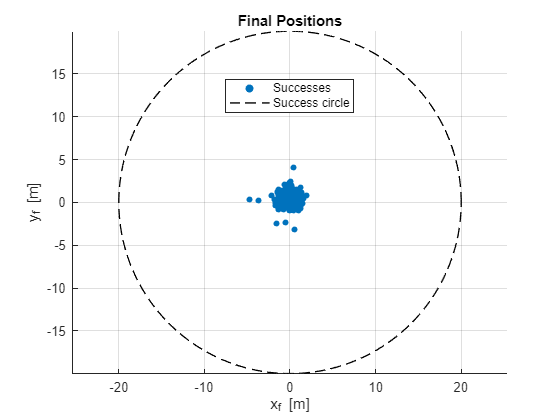

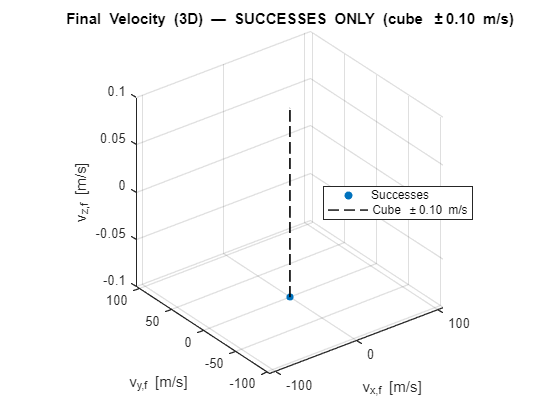

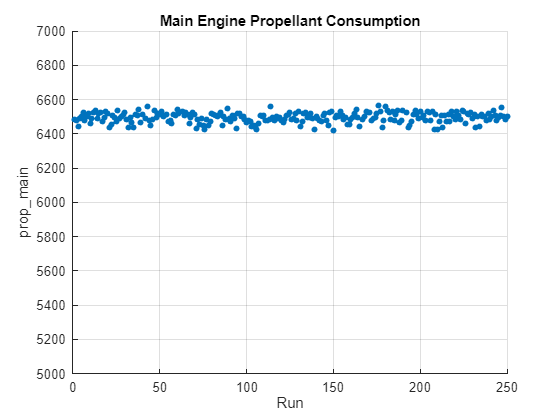

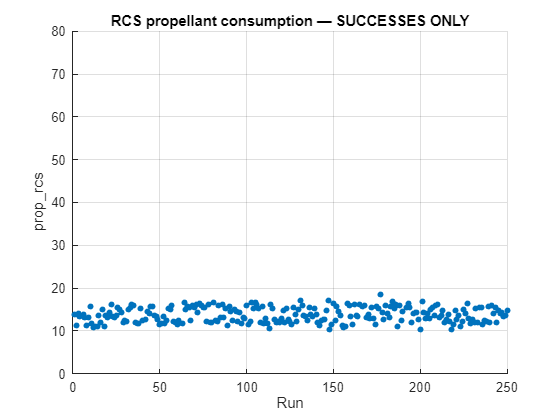

%% === PLOTS — SUCCESSES ONLY ===
if ~any(success)
    warning('No successful runs: nothing to plot.');
else
    idx_s   = find(success);
    pos_s   = pos_f(success,:);     % Nsucc x 3
    vel_s   = vel_f(success,:);     % Nsucc x 3
    pm_s    = prop_main(success);   % Nsucc x 1
    pr_s    = prop_rcs(success);    % Nsucc x 1

    % 1) Final position (XY) — successes only (reference circle R=R_xy)
    figure('Name','Monte Carlo - Final Position (XY) [SUCCESSES]');
    scatter(pos_s(:,1), pos_s(:,2), 20, 'filled'); grid on; axis equal; hold on;
    th = linspace(0, 2*pi, 360);
    plot(R_xy*cos(th), R_xy*sin(th), 'k--', 'LineWidth', 1); % reference
    xlabel('x_f [m]'); ylabel('y_f [m]');
    title(sprintf('Final Positions', R_xy));
    legend('Successes','Success circle','Location','best');
 
    % 2) Final velocity (3D) — successes only (±0.10 cube as visual reference)
    figure('Name','Monte Carlo - Final Velocity (3D) [SUCCESSES]');
    scatter3(vel_s(:,1), vel_s(:,2), vel_s(:,3), 20, 'filled'); grid on; axis vis3d; hold on;
    xlabel('v_{x,f} [m/s]'); ylabel('v_{y,f} [m/s]'); zlabel('v_{z,f} [m/s]');
    title(sprintf('Final Velocity (3D) — SUCCESSES ONLY (cube \\pm%.2f m/s)', V_th_plot));
    % Draw ±V_th_plot cube
    v = V_th_plot * [-1 -1 -1;  1 -1 -1;  -1  1 -1;  1  1 -1;  -1 -1  1;  1 -1  1;  -1  1  1;  1  1  1];
    E = [1 2;1 3;1 5;2 4;2 6;3 4;3 7;4 8;5 6;5 7;6 8;7 8];
    for e = 1:size(E,1)
        plot3(v(E(e,:),1), v(E(e,:),2), v(E(e,:),3), 'k--', 'LineWidth', 1);
    end
    legend('Successes', sprintf('Cube \\pm%.2f m/s', V_th_plot), 'Location','best');

    % 3) Main propellant — successes only
    figure('Name','Monte Carlo - prop_main [SUCCESSES]');
    scatter(idx_s, pm_s, 20, 'filled'); grid on;
    xlabel('Run'); ylabel('prop\_main'); title('Main Engine Propellant Consumption');
    ylim([5000 7000])

    % 4) RCS propellant — successes only
    figure('Name','Monte Carlo - prop_rcs [SUCCESSES]');
    scatter(idx_s, pr_s, 20, 'filled'); grid on;
    xlabel('Run'); ylabel('prop\_rcs'); title('RCS propellant consumption — SUCCESSES ONLY');
    ylim([0 80])
end

%% === STATISTICS — SUCCESSES ONLY (mean & standard deviation) ===
if any(success)
    % ---- Propellant ----
    pm_s = prop_main(success);   % main propellant (successes)
    pr_s = prop_rcs(success);    % rcs  propellant (successes)

    prop_main_mean_success = mean(pm_s, 'omitnan');
    prop_main_std_success  = std(pm_s, 0, 'omitnan');   % sample std

    prop_rcs_mean_success  = mean(pr_s, 'omitnan');
    prop_rcs_std_success   = std(pr_s, 0, 'omitnan');   % sample std

    % ---- Final XY position ----
    xf_s = pos_f(success,1);
    yf_s = pos_f(success,2);

    % components
    pos_xy_mean_success = [ mean(xf_s,'omitnan'), mean(yf_s,'omitnan') ];
    pos_xy_std_success  = [ std(xf_s,0,'omitnan'), std(yf_s,0,'omitnan') ];

    % radius in the XY plane (distance from origin in the plane)
    dist_xy_s            = hypot(xf_s, yf_s);
    dist_xy_mean_success = mean(dist_xy_s,'omitnan');
    dist_xy_std_success  = std(dist_xy_s,0,'omitnan');

    % ---- Final velocity ----
    vx_s = vel_f(success,1);
    vy_s = vel_f(success,2);
    vz_s = vel_f(success,3);

    vel_mean_success = [ mean(vx_s,'omitnan'), mean(vy_s,'omitnan'), mean(vz_s,'omitnan') ];
    vel_std_success  = [ std(vx_s,0,'omitnan'), std(vy_s,0,'omitnan'), std(vz_s,0,'omitnan') ];

    speed_s             = sqrt(vx_s.^2 + vy_s.^2 + vz_s.^2);  % |v|
    speed_mean_success  = mean(speed_s,'omitnan');
    speed_std_success   = std(speed_s,0,'omitnan');

    % ---- Final angles (DEG) ----
    phi_s   = eul_f_deg(success,1);
    theta_s = eul_f_deg(success,2);
    psi_s   = eul_f_deg(success,3);

    eul_mean_success = [ mean(phi_s,'omitnan'), mean(theta_s,'omitnan'), mean(psi_s,'omitnan') ];
    eul_std_success  = [ std(phi_s,0,'omitnan'), std(theta_s,0,'omitnan'), std(psi_s,0,'omitnan') ];

    ang_inf_s            = max(abs([phi_s, theta_s, psi_s]), [], 2);  % ||angles||_∞ per run
    ang_inf_mean_success = mean(ang_inf_s,'omitnan');
    ang_inf_std_success  = std(ang_inf_s,0,'omitnan');

    % ---- Report ----
    n_succ = sum(success);
    fprintf('Statistics (successes only) — runs: %d/%d\n', n_succ, N);
    fprintf('  main: mean = %.3f, std = %.3f\n', prop_main_mean_success, prop_main_std_success);
    fprintf('  rcs : mean = %.3f, std = %.3f\n', prop_rcs_mean_success,  prop_rcs_std_success);
    fprintf('  pos XY: mean = [%.3f, %.3f] m, std = [%.3f, %.3f] m\n', ...
            pos_xy_mean_success(1), pos_xy_mean_success(2), ...
            pos_xy_std_success(1),  pos_xy_std_success(2));
    fprintf('  |pos|_XY: mean = %.3f m, std = %.3f m\n', ...
            dist_xy_mean_success, dist_xy_std_success);
    fprintf('  vel   : mean = [%.3f, %.3f, %.3f] m/s, std = [%.3f, %.3f, %.3f] m/s\n', ...
            vel_mean_success(1), vel_mean_success(2), vel_mean_success(3), ...
            vel_std_success(1),  vel_std_success(2),  vel_std_success(3));
    fprintf('  |v|   : mean = %.3f m/s, std = %.3f m/s\n', ...
            speed_mean_success, speed_std_success);
    fprintf('  eul°  : mean = [%.3f, %.3f, %.3f] deg, std = [%.3f, %.3f, %.3f] deg\n', ...
            eul_mean_success(1), eul_mean_success(2), eul_mean_success(3), ...
            eul_std_success(1),  eul_std_success(2),  eul_std_success(3));
    fprintf('  ||eul||_∞: mean = %.3f deg, std = %.3f deg\n', ...
            ang_inf_mean_success, ang_inf_std_success);

    % ---- Save to .mat (append) ----
    save('mc_results.mat', ...
         'prop_main_mean_success','prop_main_std_success', ...
         'prop_rcs_mean_success','prop_rcs_std_success', ...
         'pos_xy_mean_success','pos_xy_std_success', ...
         'dist_xy_mean_success','dist_xy_std_success', ...
         'vel_mean_success','vel_std_success', ...
         'speed_mean_success','speed_std_success', ...
         'eul_mean_success','eul_std_success', ...
         'ang_inf_mean_success','ang_inf_std_success', ...
         '-append');

fprintf(['Success (XY dist <= %.1f m  &  |vx|,|vy|,|vz| <= %.2f m/s  &  ', ...
         '|angles_deg| <= [%.1f %.1f %.1f]°): %.2f %%   (failed runs: %d/%d)\n'], ...
         R_xy, V_th, EUL_th_deg(1), EUL_th_deg(2), EUL_th_deg(3), pct_success, n_failed, N);
else
    warning('No successful runs: unable to compute mean/standard deviation.');
end

Statistics (successes only) — runs: 246/250


  main: mean = 6495.638, std = 30.121


  rcs : mean = 13.752, std = 1.748


  pos XY: mean = [-0.071, 0.458] m, std = [0.854, 0.814] m


  |pos|_XY: mean = 1.095 m, std = 0.634 m


  vel   : mean = [0.004, 0.009, -0.100] m/s, std = [0.015, 0.009, 0.000] m/s


  |v|   : mean = 0.102 m/s, std = 0.001 m/s


  eul°  : mean = [0.011, -0.003, 0.033] deg, std = [0.053, 0.039, 0.019] deg


  ||eul||_∞: mean = 0.059 deg, std = 0.020 deg


Success (XY dist <= 20.0 m  &  |vx|,|vy|,|vz| <= 0.11 m/s  &  |angles_deg| <= [3.0 3.0 3.0]°): 98.40 %   (failed runs: 0/250)
